# Trajectory Generation

**TASK: **Approximate the following trajectory using a set of points.

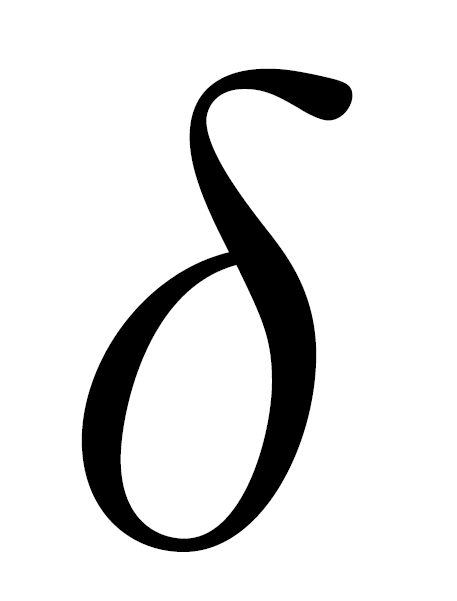

**STRATEGY:** First choose an adequate number of points in the xy plane and then rototranslate them, so that they lie in an inclined plane.

Dimensions are scaled with respect to a unitary box.

clc; clear; close all;

## Shape in the xy plane

#### Sampling points (17 points for the best approximation of the letter)

P = [[0.90; 0.07; 0] [0.80; 0.04; 0] [0.63; 0.02; 0] [0.55; 0.03; 0] [0.44; 0.08; 0] ...
     [0.43; 0.18; 0] [0.56; 0.33; 0] [0.75; 0.52; 0] [0.75; 0.73; 0] [0.58; 0.92; 0] ...
     [0.38; 0.98; 0] [0.19; 0.94; 0] [0.06; 0.79; 0] [0.16; 0.58; 0] [0.34; 0.45; 0] ...
     [0.49; 0.40; 0] [0.61; 0.38; 0]]; % Points along the trajectory
 
width_original_image = 127;
height_original_image = 225.6;
ratio = height_original_image/width_original_image;

P(2,:) = P(2,:)*ratio;

#### Curvilinear abscissa

dist = zeros(1,size(P,2));
for i = 2:size(P,2)
    dist(i) = dist(i-1) + norm(P(:,i)-P(:,1));
end

#### Spline interpolation

nPoints_spline = 100;

% N.B.: Specify the second input with two extra values [0 y 0] to signify
% that the endpoint slopes are both zero! Velocity must be zero at the
% beginning and at the end of the trajectory
piecewise_poly = spline(dist(1,:),[[0;0] P(1:2,:) [0;0]]);

spline_points = ppval(piecewise_poly,linspace(0,dist(end),nPoints_spline));
spline_points = [spline_points; zeros(1,nPoints_spline)];

#### Plot the sampled trajectory and the interpolated one

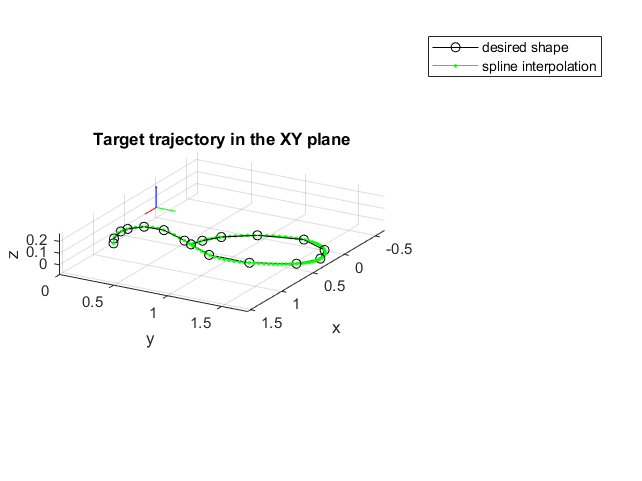

figure
hold on
p1 = plot3(P(1,:),P(2,:),P(3,:),'k-o');
p2 = plot3(spline_points(1,:),spline_points(2,:),spline_points(3,:),'g.-');
grid on

frame_scaling_factor = 5;
plot_frame(eye(3),zeros(3,1),frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(120,20)
title('Target trajectory in the XY plane')
legend([p1 p2], 'desired shape', 'spline interpolation')

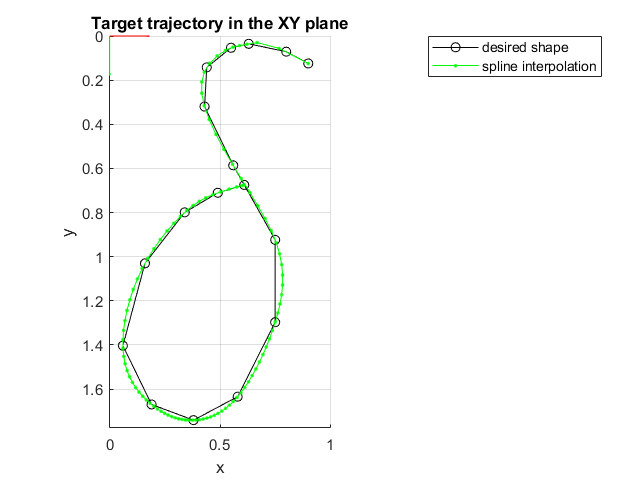

figure
hold on
p1 = plot3(P(1,:),P(2,:),P(3,:),'k-o');
p2 = plot3(spline_points(1,:),spline_points(2,:),spline_points(3,:),'g.-');
grid on

frame_scaling_factor = 5;
plot_frame(eye(3),zeros(3,1),frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
xlim([0 1]); ylim([0 1*ratio])
view(0,-90)
title('Target trajectory in the XY plane')
legend([p1 p2], 'desired shape', 'spline interpolation')

#### Scale the whole shape (compression or dilation)

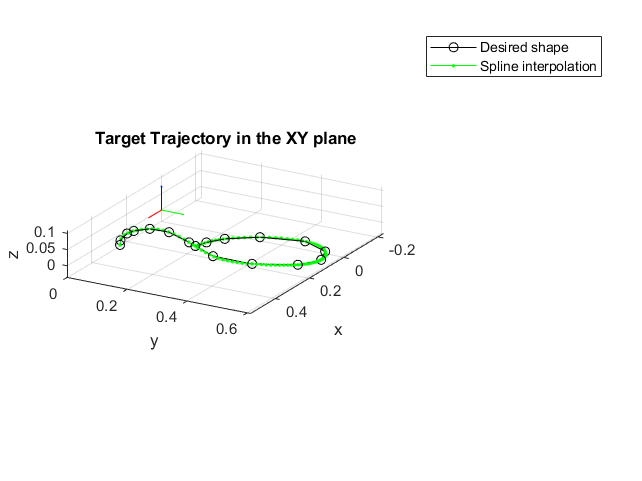

dilation_factor = 0.35;
P = dilation_factor*P;
spline_points = dilation_factor*spline_points;

figure
hold on
p1 = plot3(P(1,:),P(2,:),P(3,:),'k-o');
p2 = plot3(spline_points(1,:),spline_points(2,:),spline_points(3,:),'g.-');
grid on

frame_scaling_factor = 12;
plot_frame(eye(3),zeros(3,1),frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(120,20)
title('Target Trajectory in the XY plane')
legend([p1 p2], 'Desired shape', 'Spline interpolation')

## Shape in the XYZ space

The trajectory must lie all in the robot workspace (possibly away from the singular configurations).

#### Specify target plane (rototranslation of the shape)

x_tilt = deg2rad(45);
y_tilt = deg2rad(65);
z_tilt = deg2rad(10);

x_offset = 0.95;
y_offset = 0.3;
z_offset = 0.8;

Rx = [1     0            0
      0 cos(x_tilt) -sin(x_tilt)
      0 sin(x_tilt)  cos(x_tilt)];
  
Ry = [ cos(y_tilt) 0 sin(y_tilt)
           0       1     0
      -sin(y_tilt) 0 cos(y_tilt)];
  
Rz = [cos(z_tilt) -sin(z_tilt) 0
      sin(z_tilt)  cos(z_tilt) 0
          0            0       1];
  
R = Rx*Ry*Rz;

T = [x_offset; y_offset; z_offset];

M_target = [  R   T
            0 0 0 1];
        
P_homo = [P; ones(1,size(P,2))];
P_target = M_target*P_homo;

spline_points_homo = [spline_points; ones(1,size(spline_points,2))]; 
spline_points_target = M_target*spline_points_homo;

#### Plot the final, rototranslated, shape of the trajectory (and the interpolated one)

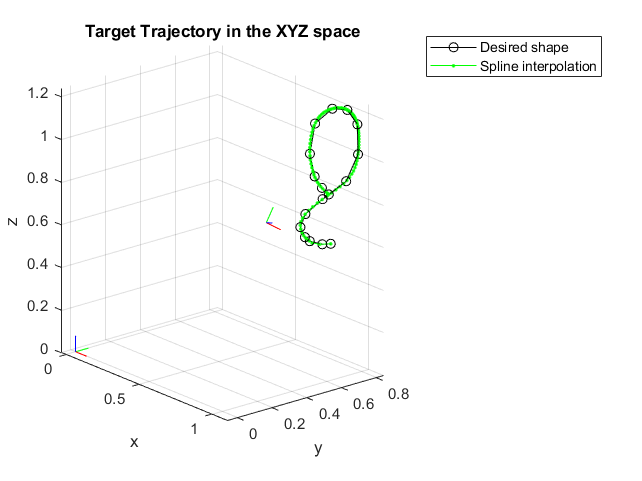

figure
hold on
p1 = plot3(P_target(1,:),P_target(2,:),P_target(3,:),'k-o');
p2 = plot3(spline_points_target(1,:),spline_points_target(2,:),spline_points_target(3,:),'g.-');
grid on

plot_frame(eye(3),zeros(3,1),frame_scaling_factor)
plot_frame(R,T,frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(50,20)
title('Target Trajectory in the XYZ space')
legend([p1 p2], 'Desired shape', 'Spline interpolation')

# Motion task definition

load_data_kinematics;

## From home to the first point of the letter

Minimum actuation time and cycloidal acceleration profile in the joint space.

Q_home = {0; 0; 0};
[S_home,~] = dir_kin(Q_home,L,angle);

S_home = cell2mat(S_home);
S_initial_shape = spline_points_target(1:3,1);

Q_home = cell2mat(Q_home);

Q0_initial_shape = inv_kin(num2cell(S_initial_shape),L,angle,1);
Q_initial_shape = cell2mat(inv_kin_numerical(num2cell(S_initial_shape),L,angle,Q0_initial_shape));

dQ = Q_initial_shape-Q_home;
abs_dQ = norm(dQ);

% Formula for the minimum actuation time in the case of cycloidal law of motion
T1_min = max([2*abs_dQ/vel_limits(2) sqrt(2*pi*abs_dQ/acc_limits(2)) sqrt(2*pi*abs_dQ/abs(acc_limits(1)))]);
T2_min = max([2*abs_dQ/vel_limits(4) sqrt(2*pi*abs_dQ/acc_limits(4)) sqrt(2*pi*abs_dQ/abs(acc_limits(3)))]);
T3_min = max([2*abs_dQ/vel_limits(6) sqrt(2*pi*abs_dQ/acc_limits(6)) sqrt(2*pi*abs_dQ/abs(acc_limits(5)))]);

Ttot = max([T1_min T2_min T3_min]);

syms l1a l1b l1c l2 l3 tilt_angle q1_sym(t) q2_sym(t) q3_sym(t) q1p_sym(t) q2p_sym(t) q3p_sym(t)
Qsymb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t)];
Qp_symb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t); q1p_sym(t); q2p_sym(t); q3p_sym(t)];

% Compute symbolic jacobian and its derivative w.r.t. time
[J_symb,~] = jac_symb;
[Jp_symb,~] = jacP_symb;

% Number of points in which to compute the law of motion
nPoints = 100;

Q = zeros(3,nPoints);   Qp = zeros(3,nPoints);  Qpp = zeros(3,nPoints);
S = zeros(3,nPoints);   Sp = zeros(3,nPoints);  Spp = zeros(3,nPoints);
pos = zeros(1,nPoints);

tt = linspace(0,Ttot,nPoints);
for i = 1:nPoints
    % GRIPPER COORDINATES
    [q1,q1p,q1pp] = cycloidal(tt(i),Ttot,Q_home(1),dQ(1));
    [q2,q2p,q2pp] = cycloidal(tt(i),Ttot,Q_home(2),dQ(2));
    [q3,q3p,q3pp] = cycloidal(tt(i),Ttot,Q_home(3),dQ(3));
    
    Q(:,i) = real([q1; q2; q3]);
    Qp(:,i) = real([q1p; q2p; q3p]);
    Qpp(:,i) = real([q1pp; q2pp; q3pp]);
    
    % COORDINATES THROUGH DIRECT KINEMATICS
    [Scell,~] = dir_kin(num2cell(Q(:,i)),L,angle);
    S(:,i) = cell2mat(Scell);

    % CONVERT FROM SYMBOLIC TO NUMERICAL VALUES
    J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));
    
    % VELOCITY ARRAY
    Sp(:,i) = J*Qp(:,i);    
    
    % ACCELERATION ARRAY
    Spp(:,i) = J*Qpp(:,i)+Jp*Qp(:,i);
    
    % POSITION OF THE GRIPPER ALONG THE TRAJECTORY
    % (velocity and acceleration are computed afterwards using diff()/dT)
    pos(i) = norm(S(1:3,i) - S(1:3,1));
        
    %%%%% END KINEMATICS %%%%%
end

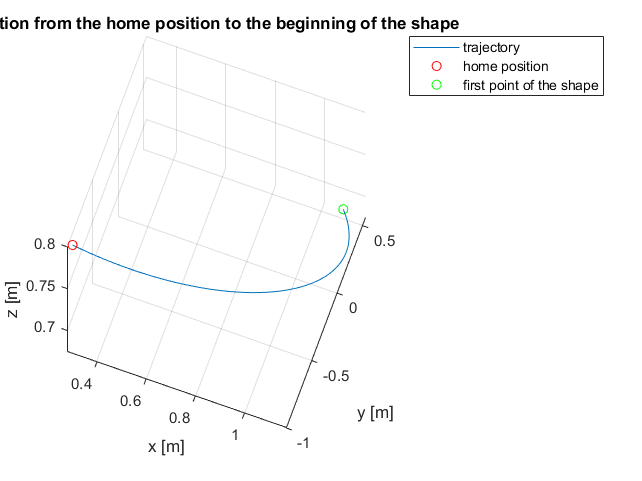

figure('name','Motion from home to first point of the shape','NumberTitle','off')
plot3(S(1,:),S(2,:),S(3,:))              % Trajectory
hold on
plot3(S_home(1),S_home(2),S_home(3),'or')                               % Home point (original)
plot3(S_initial_shape(1),S_initial_shape(2),S_initial_shape(3),'og')    % First point of the shape (original)
grid on
view(20,65)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Motion from the home position to the beginning of the shape');
legend('trajectory','home position','first point of the shape');

## Along the shape of the letter

Points connected using the spline algorithm

#### Compute the minimum sampling time to respect kinematic limits

S_initial_shape = spline_points_target(1:3,1);

Q0_initial_shape = inv_kin(num2cell(S_initial_shape),L,angle,1);
Q_initial_shape = cell2mat(inv_kin_numerical(num2cell(S_initial_shape),L,angle,Q0_initial_shape));

S_shape = [spline_points_target(1:3,1) spline_points_target(1:3,:) spline_points_target(1:3,end);]; % To assure start and end null velocity

syms l1a l1b l1c l2 l3 tilt_angle q1_sym(t) q2_sym(t) q3_sym(t) q1p_sym(t) q2p_sym(t) q3p_sym(t)
Qsymb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t)];
Qp_symb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t); q1p_sym(t); q2p_sym(t); q3p_sym(t)];

% Compute symbolic jacobian and its derivative w.r.t. time
[J_symb,~] = jac_symb;
[Jp_symb,~] = jacP_symb;

% Number of points in which to compute the law of motion --> is the number
% of interpolation points obtained with the spline
nPoints = size(S_shape,2);

% Compute sampling time in order to respect velocity and acceleration
% constraints of the joints
dT = 0.01; % Initial guess
Qp = [Inf; Inf; Inf]; Qpp = [Inf; Inf; Inf];
Q0 = num2cell(Q_initial_shape);

while max(Qp,[],2) > vel_limits([2 4 6])' | max(Qp,[],2) > acc_limits([2 4 6])'
    xp_shape_diff = diff(S_shape(1,:),[],2)/dT;
    yp_shape_diff = diff(S_shape(2,:),[],2)/dT;
    zp_shape_diff = diff(S_shape(3,:),[],2)/dT;
    Sp_shape_diff = [[0; 0; 0] [xp_shape_diff; yp_shape_diff; zp_shape_diff]];
    
    xpp_shape_diff = diff(Sp_shape_diff(1,:),[],2)/dT;
    ypp_shape_diff = diff(Sp_shape_diff(2,:),[],2)/dT;
    zpp_shape_diff = diff(Sp_shape_diff(3,:),[],2)/dT;
    Spp_shape_diff = [[0; 0; 0] [xpp_shape_diff; ypp_shape_diff; zpp_shape_diff]];
    
    for i = 1:nPoints    
        % JOINT COORDINATES THROUGH INVERSE KINEMATICS
        Qcell = inv_kin_numerical(num2cell(S_shape(1:3,i)),L,angle,Q0);
        Q(:,i) = cell2mat(Qcell);
        Q0 = num2cell(Q(:,i));
        
        % CONVERT FROM SYMBOLIC TO NUMERICAL VALUES
        J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    
        Qp(:,i) = J^-1*Sp_shape_diff(:,i);
        
        Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));
        
        Qpp(:,i) = J^-1*(Spp_shape_diff(:,i)-Jp*Qp(:,i));
    end
    
    if max(Qp,[],2) <= vel_limits([2 4 6])' & max(Qp,[],2) <= acc_limits([2 4 6])'
        break
    end
    
    dT = 1.1*dT;
end

% Minimum sampling time to respect velocity and acceleration constraints of actuators
disp(dT) 

    0.0110



% Minimum sampling time (ROUNDED) to respect velocity and acceleration constraints of actuators
dT = ceil(dT*100);
dT = dT/100;
disp(dT) 

    0.0200



#### Loop for each sampling point

xp_shape_diff = diff(S_shape(1,:),[],2)/dT;
yp_shape_diff = diff(S_shape(2,:),[],2)/dT;
zp_shape_diff = diff(S_shape(3,:),[],2)/dT;
Sp_shape_diff = [[0; 0; 0] [xp_shape_diff; yp_shape_diff; zp_shape_diff]];

xpp_shape_diff = diff(Sp_shape_diff(1,:),[],2)/dT;
ypp_shape_diff = diff(Sp_shape_diff(2,:),[],2)/dT;
zpp_shape_diff = diff(Sp_shape_diff(3,:),[],2)/dT;
Spp_shape_diff = [[0; 0; 0] [xpp_shape_diff; ypp_shape_diff; zpp_shape_diff]];

Q = zeros(3,nPoints);   Qp = zeros(3,nPoints);  Qpp = zeros(3,nPoints);
S = zeros(3,nPoints);   Sp = zeros(3,nPoints);  Spp = zeros(3,nPoints);

tt = (0:(nPoints-1))*dT;
Q0 = num2cell(Q_initial_shape);

for i = 1:nPoints 
    
    %%%%% BEGIN KINEMATICS %%%%%
    
    % JOINT COORDINATES THROUGH INVERSE KINEMATICS
    Qcell = inv_kin_numerical(num2cell(S_shape(:,i)),L,angle,Q0);
    Q(:,i) = cell2mat(Qcell);
    Q0 = num2cell(Q(:,i));

    % CONVERT JACOBIAN FROM SYMBOLIC TO NUMERICAL VALUES
    J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    
    % VELOCITY ARRAY
    Qp(:,i) = J^-1*Sp_shape_diff(:,i);
    
    % CONVERT DERIVATIVE OF JACOBIAN FROM SYMBOLIC TO NUMERICAL VALUES
    Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));

    % ACCELERATION ARRAY
    Qpp(:,i) = J^-1*(Spp_shape_diff(:,i)-Jp*Qp(:,i));
    
    
    %%% CHECK CORRECTNESS %%%
     % COORDINATES THROUGH DIRECT KINEMATICS
    [Scell,~] = dir_kin(num2cell(Q(:,i)),L,angle);
    S(:,i) = cell2mat(Scell);

    % CONVERT FROM SYMBOLIC TO NUMERICAL VALUES
    J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));
    
    % VELOCITY ARRAY
    Sp(:,i) = J*Qp(:,i);    
    
    % ACCELERATION ARRAY
    Spp(:,i) = J*Qpp(:,i)+Jp*Qp(:,i);
    %%% END CHECK CORRECTNESS %%%
    
    %%%%% END KINEMATICS %%%%%
    
end

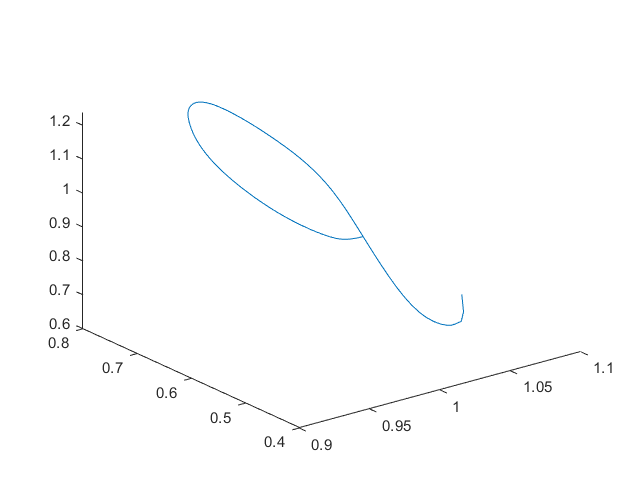

figure
plot3(S(1,:),S(2,:),S(3,:))

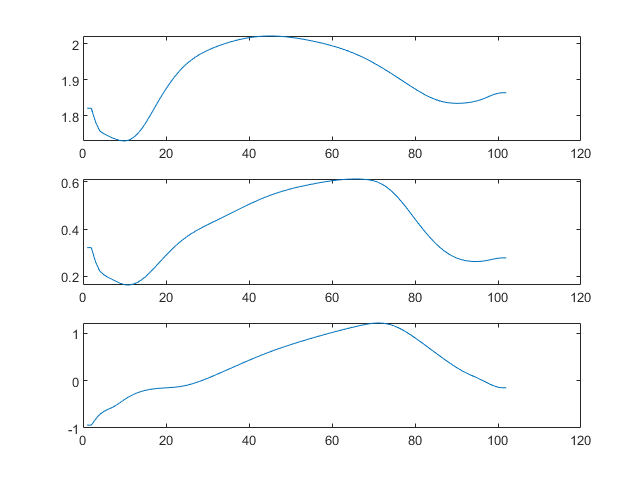

figure
tiledlayout(3,1)
nexttile
plot(Q(1,:))
nexttile
plot(Q(2,:))
nexttile
plot(Q(3,:))

## From the last point of the letter back to home

Minimum actuation time and cycloidal acceleration profile in the joint space.

% Q_home = {0; 0; 0};
% [S_home,~] = dir_kin(Q_home,L,angle);
% 
% S_home = cell2mat(S_home);
S_final_shape = spline_points_target(1:3,end);

% Q_home = cell2mat(Q_home);

Q0_final_shape = inv_kin(num2cell(S_final_shape),L,angle,1);
Q_final_shape = cell2mat(inv_kin_numerical(num2cell(S_final_shape),L,angle,Q0_final_shape));

dQ = Q_home-Q_final_shape;
abs_dQ = norm(dQ);

% % Formula for the minimum actuation time in the case of cycloidal law of motion
% T1_min = max([2*abs_dQ/vel_limits(2) sqrt(2*pi*abs_dQ/acc_limits(2)) sqrt(2*pi*abs_dQ/abs(acc_limits(1)))]);
% T2_min = max([2*abs_dQ/vel_limits(4) sqrt(2*pi*abs_dQ/acc_limits(4)) sqrt(2*pi*abs_dQ/abs(acc_limits(3)))]);
% T3_min = max([2*abs_dQ/vel_limits(6) sqrt(2*pi*abs_dQ/acc_limits(6)) sqrt(2*pi*abs_dQ/abs(acc_limits(5)))]);
% 
% Ttot = max([T1_min T2_min T3_min]);

% % syms l1a l1b l1c l2 l3 tilt_angle q1_sym(t) q2_sym(t) q3_sym(t) q1p_sym(t) q2p_sym(t) q3p_sym(t)
% Qsymb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t)];
% Qp_symb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t); q1p_sym(t); q2p_sym(t); q3p_sym(t)];

% % Compute symbolic jacobian and its derivative w.r.t. time
% [J_symb,~] = jac_symb;
% [Jp_symb,~] = jacP_symb;

% % Number of points in which to compute the law of motion
nPoints = 100;

Q = zeros(3,nPoints);   Qp = zeros(3,nPoints);  Qpp = zeros(3,nPoints);
S = zeros(3,nPoints);   Sp = zeros(3,nPoints);  Spp = zeros(3,nPoints);
pos = zeros(1,nPoints);

tt = linspace(0,Ttot,nPoints);
for i = 1:nPoints
    % GRIPPER COORDINATES
    [q1,q1p,q1pp] = cycloidal(tt(i),Ttot,Q_final_shape(1),dQ(1));
    [q2,q2p,q2pp] = cycloidal(tt(i),Ttot,Q_final_shape(2),dQ(2));
    [q3,q3p,q3pp] = cycloidal(tt(i),Ttot,Q_final_shape(3),dQ(3));
    
    Q(:,i) = real([q1; q2; q3]);
    Qp(:,i) = real([q1p; q2p; q3p]);
    Qpp(:,i) = real([q1pp; q2pp; q3pp]);
    
    % COORDINATES THROUGH DIRECT KINEMATICS
    [Scell,~] = dir_kin(num2cell(Q(:,i)),L,angle);
    S(:,i) = cell2mat(Scell);

    % CONVERT FROM SYMBOLIC TO NUMERICAL VALUES
    J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));
    
    % VELOCITY ARRAY
    Sp(:,i) = J*Qp(:,i);    
    
    % ACCELERATION ARRAY
    Spp(:,i) = J*Qpp(:,i)+Jp*Qp(:,i);
    
    % POSITION OF THE GRIPPER ALONG THE TRAJECTORY
    % (velocity and acceleration are computed afterwards using diff()/dT)
    pos(i) = norm(S(1:3,i) - S(1:3,1));
        
    %%%%% END KINEMATICS %%%%%
end

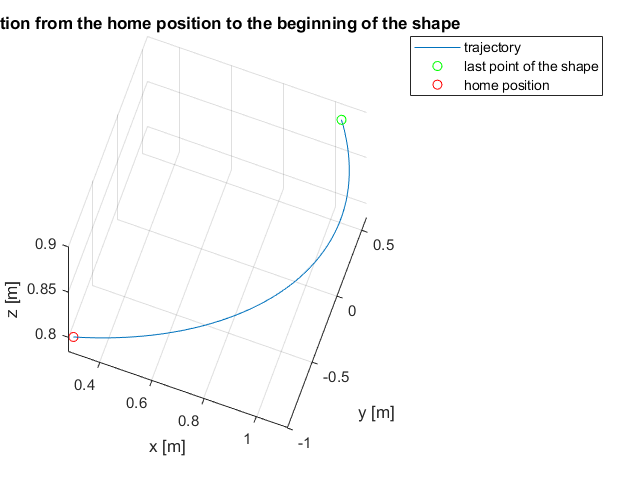

figure('name','Motion from the last point of the shape back to home','NumberTitle','off')
plot3(S(1,:),S(2,:),S(3,:))              % Trajectory
hold on
plot3(S_final_shape(1),S_final_shape(2),S_final_shape(3),'og')    % Last point of the shape
plot3(S_home(1),S_home(2),S_home(3),'or')                         % Home point
grid on
view(20,65)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Motion from the home position to the beginning of the shape');
legend('trajectory','last point of the shape','home position');